clc
clear
load b1.mat
load b2.mat
load a.mat
load vmax.mat
load maxx.mat
load M.mat
load dmdt.mat
load rainfall.mat rainfall

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Lawrence Leung 2022
% 
%
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
rainfalli = 11;   %用于循环的操作
% woodyplant = 1
% grassplant1 = 4
% %grassplant2 = 4

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

time=10;%总时间
dt=0.00001;%时间步长(越小越精确，但更占内存和时间)
len=round(time/dt);%计算总步数
m=M./2%100;%初始生物量为最大生物量的0.01

m =     0.5245    0.5315    0.5174    0.9875    1.8750    0.3500


minm=min(min(M))*0.01;




k=[2 1 5 6 3 4] %grassplant2];%在这里写要加入的植物代号（加k2就写2，加k3就写3）

k =      2     1     5     6     3     4


[w,num]=size(k);%计算植物数量num






%计算不同降水条件下的vk用(有震荡)
fun2=@(k,x,myvmax) a(5,k).*myvmax./(1+a(1,k).*exp(a(2,k).*(x-a(3,k))))+a(5,k).*myvmax./(1+a(1,k).*exp(-a(2,k).*(x-a(3,k)-a(4,k)))) - 1.5.*myvmax;
    
zx=rainfall(rainfalli, 1);%降水量波动中心值
bd=rainfall(rainfalli, 2);%降水量波动值（正负100共200）
tq=rand(1,len);
tq=bd*(tq-0.5);
tq=tq+zx;%降水量tq
%tq=zx*ones(1,len);%令降水量不变



mm=zeros(6,len);%记录各植物的数量
dmm=mm;
for t=dt:dt:time%随k2的生物量增长，k1的增长速率会如何变化
    tt=round(t/dt);
    other=0;
    for u=1:num%遍历全部植物

        f=k(u);


        %xz=minm-M(f);%允许共生和竞争
        xz=0;%只允许共生

        myvmax=vmax(f);
        for v=1:num
            other=other+b1(f,k(v))*m(k(v))^2+b2(f,k(v))*m(k(v));%计算其他植物对第u种的影响
        end
        dm=fun2(f,tq(tt),myvmax)*m(f)*(1- ( m(f)/( M(f) +max(xz,other) )));
        
        m(f)=m(f)+dm*dt;
        
        if m(f)<=minm
            m(f)=minm;
        end
        
        
        mm(f,tt)=m(f);
        dmm(f,tt)=dm;
    end
    
end

tt=1:len/2

tt =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


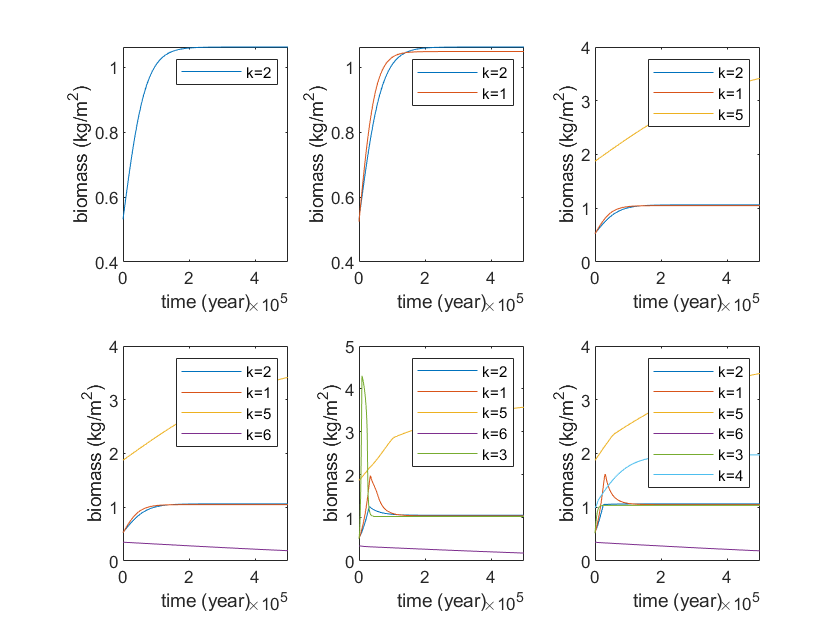


subplot(2, 3, 6)
plot(tt,mm(2,tt), tt,mm(1,tt), tt,mm(5, tt), tt,mm(6, tt), tt,mm(3, tt), tt,mm(4, tt))         %,tt,mm(grassplant1,tt))%,tt,mm(grassplant2,tt))  %画图1
legend('k=2', 'k=1', 'k=5', 'k=6', 'k=3', 'k=4')
legend('show')
xlabel('time (year)')
ylabel('biomass (kg/m^2)')
xlim([0 max(tt)])


% subplot(2, 3, rainfalli-10+3)
% plot(tt,dmm(grassplant1,tt),tt,dmm(woodyplant,tt))%画图2
% legend('k=4', 'k=1')%, 'k=4')
% legend('show')
% xlabel('time (year)')
% %ylabel(['differentation of biomass \r\n (kg/m^2/(year*10^5)'])
% xlim([0 max(tt)])

%jiange=20000;%间隔几个点
%for i=1:len/jiange
%    mmm(:,i)=mm(:,i*jiange);
    
%end
%surf(mmm)       %绘制3D图
